# APV RL Training

clear;
close all;
bdclose('all');
addpath("/home/momentumlab/Documents/git/AI-CPS-Ensemble/APV/model");

## Environment Setup

Ts = 0.1;
Ts_sample = 0.1;
Tf = 50;
freeSpotIndex = 32;
faceDirection = "south";    % parked car faces north or south
xRef = createReferenceTrajectory(Ts,Tf,freeSpotIndex);
map = ParkingLotEnvironment(freeSpotIndex,"Route",xRef);
egoInitialPose = [40 -55 pi/2];
egoTargetPose = createTargetPose(map,freeSpotIndex,faceDirection);

autoParkingValetParams3D
mdl = "APV_RL_training";
createMPCForParking3D;

## Reinforcement Learning Controller Design

Create the observation and action specifications for the environment.

nObs = 16;
nAct = 1;
observationInfo = rlNumericSpec([nObs 1]);
observationInfo.Name = "observations";
actionInfo = rlNumericSpec([nAct 1],"LowerLimit",-1,"UpperLimit",1);
actionInfo.Name = "actions";

% load simulink model
blk = mdl + "/Controller/RL Controller/RL Agent";
env = rlSimulinkEnv(mdl,blk,observationInfo,actionInfo);

Specify a reset function for training. The `autoParkingValetResetFcn` function resets the initial pose of the ego vehicle to random values at the start of each episode.

env.ResetFcn = @autoParkingValetResetFcn3D;

### Create Agent

Set the random seed generator for reproducibility.

% rng(0)

% create critic
cnet = [
    featureInputLayer(nObs,"Normalization","none","Name","State")
    fullyConnectedLayer(128, "Name", "fc1")
    concatenationLayer(1,2,"Name","concat")
    reluLayer("Name","relu1")
    fullyConnectedLayer(128, "Name","fc3")
    reluLayer("Name","relu2")
    fullyConnectedLayer(1,"Name","CriticOutput")];

actionPath = [
    featureInputLayer(nAct,"Normalization","none","Name","Action")
    fullyConnectedLayer(128,"Name","fc2")];

criticNet = layerGraph(cnet);
criticNet = addLayers(criticNet, actionPath);
criticNet = connectLayers(criticNet,"fc2","concat/in2");

criticdlnet = dlnetwork(criticNet);
critic1 = rlQValueFunction(criticNet,observationInfo,actionInfo,...
    "ObservationInputNames","State","ActionInputNames","Action");
critic2 = rlQValueFunction(criticNet,observationInfo,actionInfo,...
    "ObservationInputNames","State","ActionInputNames","Action");

% create actor
statePath = [
    featureInputLayer(nObs, 'Normalization','none','Name','observation')
    fullyConnectedLayer(128, 'Name','commonFC1')
    reluLayer('Name','CommonRelu1')
    fullyConnectedLayer(64, 'Name','commonFC2')
    reluLayer('Name','CommonRelu2')];

meanPath = [
    fullyConnectedLayer(32,'Name','MeanFC1')
    reluLayer('Name','MeanRelu1')
    fullyConnectedLayer(nAct,'Name','Mean')];

stdPath = [
    fullyConnectedLayer(nAct,'Name','StdFC1')
    reluLayer('Name','StdRelu1')
    softplusLayer('Name','StandardDeviation')];

actorNetwork = layerGraph(statePath);
actorNetwork = addLayers(actorNetwork,meanPath);
actorNetwork = addLayers(actorNetwork,stdPath);

actorNetwork = connectLayers(actorNetwork,'CommonRelu2','MeanFC1/in');
actorNetwork = connectLayers(actorNetwork,'CommonRelu2','StdFC1/in');

actor = rlContinuousGaussianActor(actorNetwork, observationInfo, actionInfo, ...
    'ActionMeanOutputNames','Mean',...
    'ActionStandardDeviationOutputNames','StandardDeviation',...
    'ObservationInputNames','observation');
% Options for SAC agent
agentOpts = rlSACAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'TargetUpdateFrequency',1,...
    'ExperienceBufferLength',1e6,...
    'NumStepsToLookAhead',1,...
    'MiniBatchSize',128,...
    'DiscountFactor',0.99);

% agentOpts.ExplorationModel.StandardDeviation = 0.1;
% agentOpts.ExplorationModel.StandardDeviationDecayRate = 1e-4;
% agentOpts.ExplorationModel.StandardDeviationMin = 0.01;

% Actor optimizer options
agentOpts.ActorOptimizerOptions.LearnRate = 1e-3;
agentOpts.ActorOptimizerOptions.GradientThreshold = 1;
agentOpts.ActorOptimizerOptions.L2RegularizationFactor = 1e-3;

% Critic optimizer options
agentOpts.CriticOptimizerOptions(1).LearnRate = 2e-3;
agentOpts.CriticOptimizerOptions(2).LearnRate = 2e-3;
agentOpts.CriticOptimizerOptions(1).GradientThreshold = 1;
agentOpts.CriticOptimizerOptions(2).GradientThreshold = 1;

% agent creation
agent = rlSACAgent(actor,[critic1 critic2], agentOpts);

### Train Agent

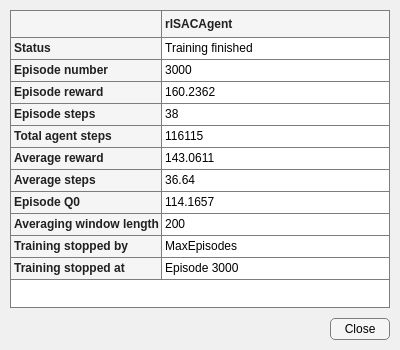

% semantics reward weights: [2,0.5,0.05] (default)
distWeight = 3;
orientWeight = 0.5;
stableWeight = 0.05;
rewardWeights = [distWeight, orientWeight, stableWeight];
maxsteps = 200;

trainOpts = rlTrainingOptions(...
    "MaxEpisodes",3000,...
    "MaxStepsPerEpisode",maxsteps,...
    "ScoreAveragingWindowLength",200,...
    "Plots","training-progress",...
    "StopTrainingCriteria","AverageReward",...
    "StopTrainingValue",300);

doTraining = true;
if doTraining
    trainingStats = train(agent,env,trainOpts);
else
    load("rlAutoParkingValetAgent.mat","agent");
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = false;

if isSave
    dateOfTrain = date;
    agentName = ['APV-SAC-', dateOfTrain(1:end-5)];
    agentName = agentName+...
        "-"+string(rewardWeights(1))+...
        "-"+string(rewardWeights(2))+...
        "-"+string(rewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agent, ...
                 'rewardWeights', rewardWeights, ...
                 'agentOptions', agentOpts, ...
                 'criticNetwork', criticNet, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/APV/DRL_training/trained_agent/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved')
end

APV-SAC-11-Jul-3-0.5-0.05 saved


## Simulation & Plotting

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');

% get results
experiences = sim(env,agent,simOpts);

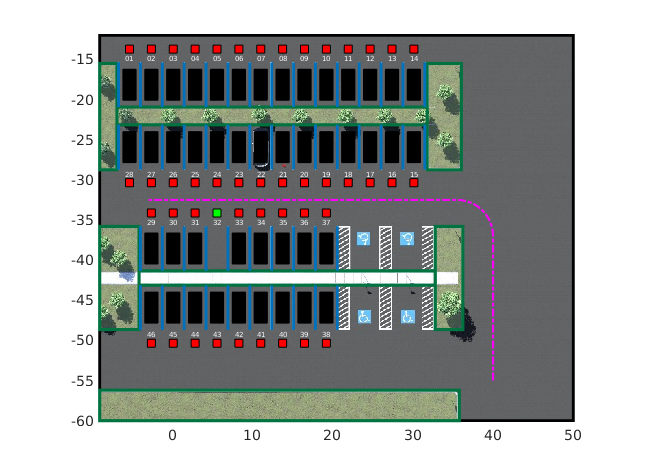

totalReward = sum(experiences.Reward);

% extract signals from simulation results
% time = experiences.SimulationInfo.tout;
% steps = size(time);
% steps = steps(1);
x_error = experiences.SimulationInfo.logsout.getElement('x_error').Values.Data;
steps = length(x_error);
time = 1:steps;

y_error =  experiences.SimulationInfo.logsout.getElement('y_error').Values.Data;
theta_error =  experiences.SimulationInfo.logsout.getElement('theta_error').Values.Data;
steer_angle =  experiences.SimulationInfo.logsout.getElement('steer_angle').Values.Data;
lidar_min_dist =  experiences.SimulationInfo.logsout.getElement('lidar_min_dist').Values.Data;
is_parked =  experiences.SimulationInfo.logsout.getElement('is_parked').Values.Data;
is_collision =  experiences.SimulationInfo.logsout.getElement('is_collision').Values.Data;

% theta_error = reshape(theta_error, [steps,1]);


figure(1);

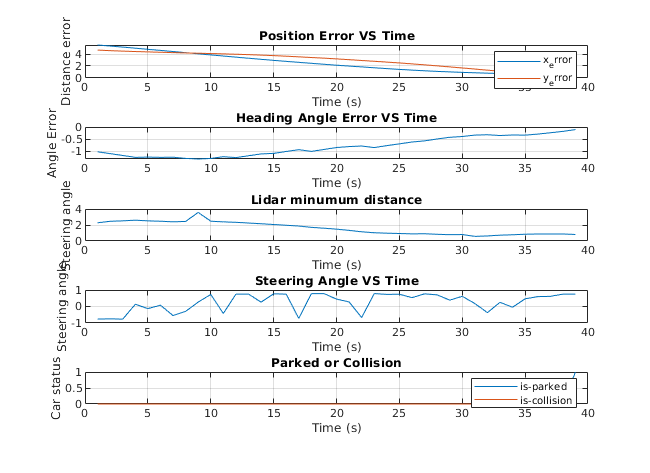

subplot(5,1,1)
plot(time,x_error, time,y_error)
title('Position Error VS Time')
legend('x_error', 'y_error')
xlabel('Time (s)') 
ylabel('Distance error') 
grid on

subplot(5,1,2)
plot(time,theta_error)
title('Heading Angle Error VS Time')
xlabel('Time (s)') 
ylabel('Angle Error') 
grid on

subplot(5,1,3)
plot(time,lidar_min_dist)
title('Lidar minumum distance')
xlabel('Time (s)') 
ylabel('Steering angle') 
grid on

subplot(5,1,4)
plot(time,steer_angle)
title('Steering Angle VS Time')
xlabel('Time (s)') 
ylabel('Steering angle') 
grid on
subplot(5,1,5)
plot(time,is_parked, time,is_collision)
title('Parked or Collision')
xlabel('Time (s)') 
legend('is-parked', 'is-collision')
ylabel('Car status') 
grid on

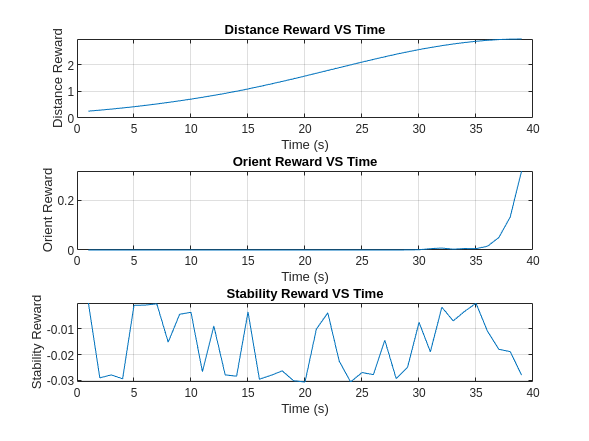

figure(2);
dist_reward =  experiences.SimulationInfo.logsout.getElement('dist_reward').Values.Data;
orient_reward =  experiences.SimulationInfo.logsout.getElement('orient_reward').Values.Data;
stable_reward =  experiences.SimulationInfo.logsout.getElement('stable_reward').Values.Data;

subplot(3,1,1)
plot(time,dist_reward)
title('Distance Reward VS Time')
xlabel('Time (s)') 
ylabel('Distance Reward') 
grid on

subplot(3,1,2)
plot(time,orient_reward)
title('Orient Reward VS Time')
xlabel('Time (s)') 
ylabel('Orient Reward') 
grid on

subplot(3,1,3)
plot(time,stable_reward)
title('Stability Reward VS Time')
xlabel('Time (s)') 
ylabel('Stability Reward') 
grid on

## Training progress info

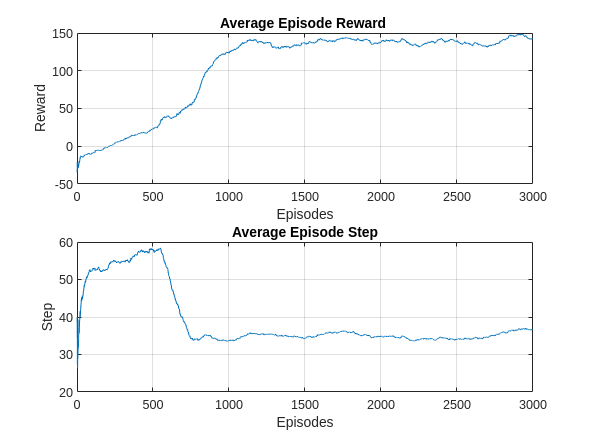

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(3);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on